wpts = [0 0.2 0.5 9; 0 0.3 0.5 0.7];
tpts = 0:0.33:1;
numsamples = 100;

[q,qd,qdd,qddd,pp,timepoints,tsamples] = minjerkpolytraj(wpts,tpts,numsamples);

plot(tsamples,q)
hold on
plot(timepoints,wpts,'x')
xlabel('t')
ylabel('Positions')
legend('X-positions','Y-positions')
hold off

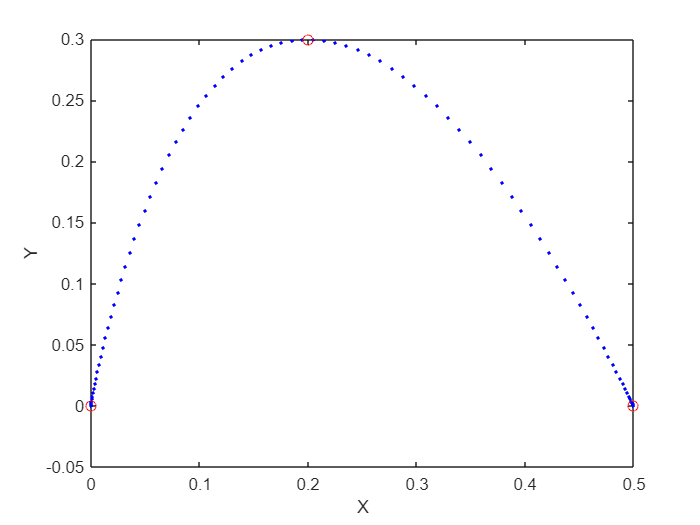


figure
plot(tsamples,qd)
hold on
plot(timepoints,wpts,'x')
xlabel('t')
ylabel('Velocity')
legend('X-Velocity','Y-Velocity')
hold off

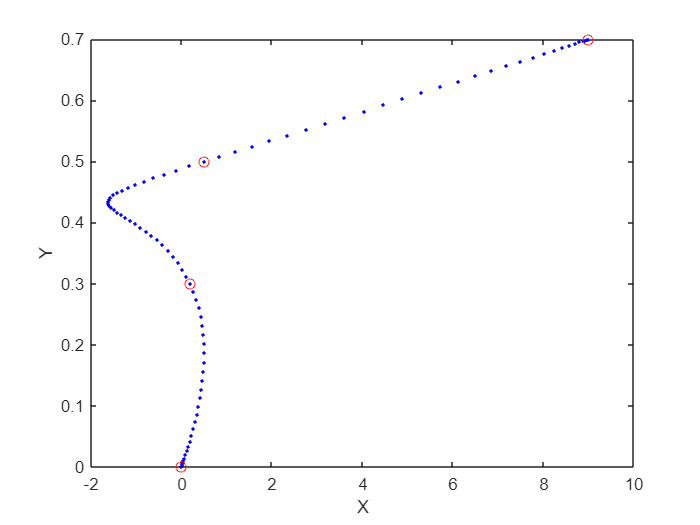



figure
plot(q(1,:),q(2,:),'.b',wpts(1,:),wpts(2,:),'or')
xlabel('X')
ylabel('Y')